# Casting Shadows

MATLAB [Graphics and App Building Blog](https://blogs.mathworks.com/graphics-and-apps/)

*Contributor: *[*Eric Ludlam*](https://www.mathworks.com/matlabcentral/profile/authors/869244) 

*Joining us again is Eric Ludlam, development manager of the MATLAB charting team. Discover more about Eric on our *[*contributors bio page**.*](https://blogs.mathworks.com/graphics-and-apps/contributors/)

MATLAB Graphics supports 3D shapes and lighting properties, but the light objects don't cast shadows.  Let's explore a way to cast a shadow on the Axes box.  Maybe something like this:

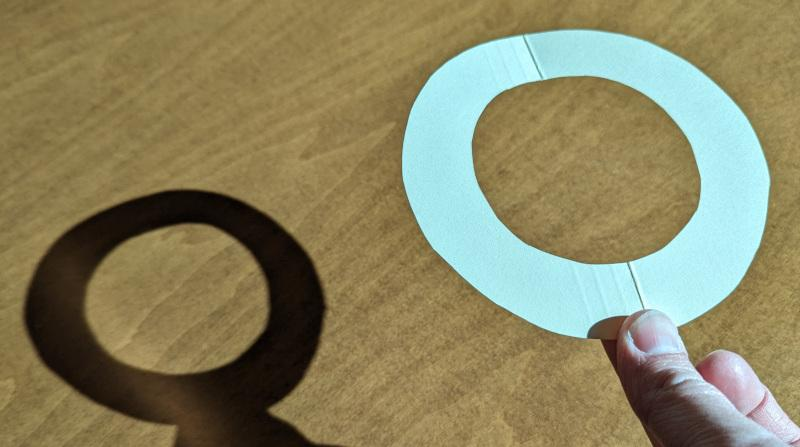

Today I'd like to explore a simple way to compute and draw shadows on the floor of your axes.  Let's start by creating a shape that will cast a shadow.  I'll go with a donut shaped ribbon similar to the photo above, but to make it more interesting, I'll oscillate the perimeter.

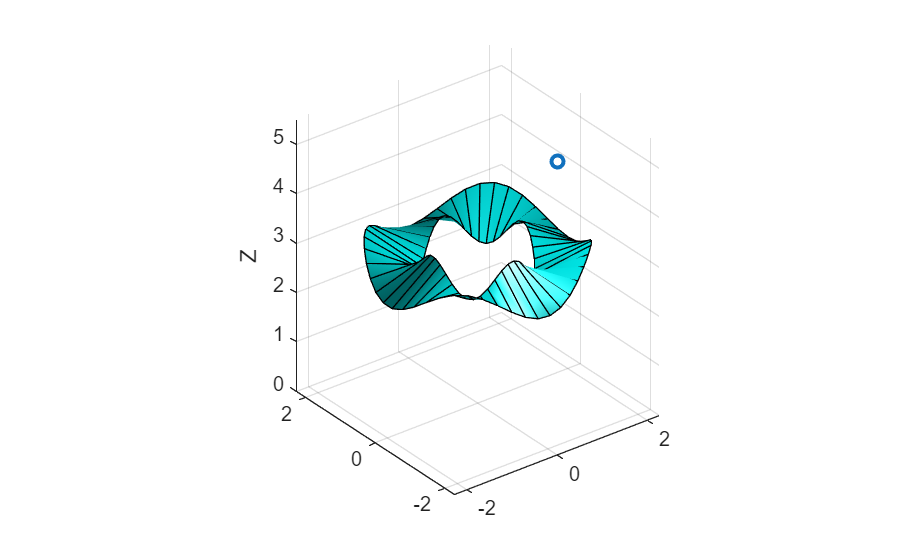

sz=50;
t=linspace(0,2,sz)';
x=cospi(t);
y=sinpi(t);
z=cospi(t*4)/3; % oscillate

verts=[x y z+3 % inner ring
       x*2 y*2 -z+3]; % outer ring

faces = [ 1:sz
          2:sz 1
          [2:sz 1]+sz
          (1:sz)+sz ]';

P=patch('Vertices',verts,'Faces',faces,...
        'FaceColor', 'cyan', 'EdgeColor','black','FaceLighting','gouraud');

% Axes styles
view(3)
daspect([1 1 1])
grid on
axis padded

% Add a "local" light object into the scene
Lpos = [1 -1 5]; % Save position of the light object for later
L=light('Position',Lpos,'Style','local');

% Place a marker where the light will be
Lm=line(Lpos(1),Lpos(2),Lpos(3),'Marker','o','LineWidth',2,'MarkerFaceColor','auto');

% Set ZLim to include zero to simplify the shadow computation
zlim([0 5.5])
zlabel('Z')

This provides a shape and a light.  Now we can explore how to compute a shadow.

To start, think of the light as a single point in space with a line extending from it to a vertex within the patch.  We can use the slope-intercept formula to compute where on the Z=0 plane the line of light will intersect.  That, of course is:


$$y=mx+b$$


The point in space (x & y) we'll say is the point where the shadow sits on the floor of the Axes which is what we want to solve for.  We'll call that `Sx` and for y we'll use `Sz`.  The slope m is the change in y over change in x, but since we're substituting in z for y, we get:


$$\frac{V_z-L_z}{V_x-L_x}$$


where we compute the slope using the point V (vertex on our patch) and the light position L.  Lastly, b is the y-intercept,  We can use the Z value of the Light `Lz` for now, but it doesn't account for the light's position at `Lx`.  To fix that, we need to offset the shadow's `X` coordinate by `Lx`. Making these substitutions gives us:


$$S_z = \left(\frac{V_z-L_z}{V_x-L_x}\right)(S_x-L_x)+L_z$$
 

We already know the value of `Sz` which in our example is 0, or the floor of the Axes.  With `Sz` as `0` and solving for `Sx`, we get:


$$(S_x-L_x) = -L_z \div  \left(\frac{V_z-L_z}{V_x-L_x}\right)$$
    

or


$$S_x = \left(\frac{V_x-L_x}{L_z-V_z}\right)L_z+L_x
$$


Here's what it looks like with a couple concrete numbers if `Sz=0` and `Lx=0`:

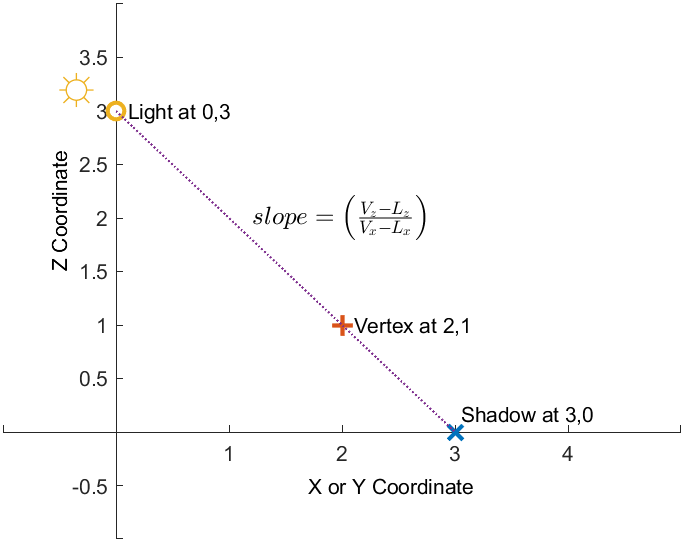

If we plug in the numbers, we get:

disp(3 * ((2-0)/(3-1)) + 0);

     3



The following code is in three dimensions which means we do two independent computations, one for `X,Z`, and the other for `Y,Z`, where `Z==0` is the plane we cast the shadow to.  Both computations will use the same equation.

When we pre-allocate the shadow vertices, we also assign all the Z values to zero which is the floor of our axes.  We can then compute both the X and Y flavors of our formula for every vertex in our vertex array.  We do this by vectorizing the computation of the `shadowVerts` array.

shadowVerts = zeros(size(verts));
shadowVerts(:,1:2) = Lpos(3).*(verts(:,1:2)-Lpos(1:2))./(Lpos(3)-verts(:,3))+Lpos(1:2);

Now that we have the shadow vertices, we can draw the shadow.  Since the `shadowVerts` array is in the same order as the original (`verts`) array, we can recycle the faces array we computed earlier.

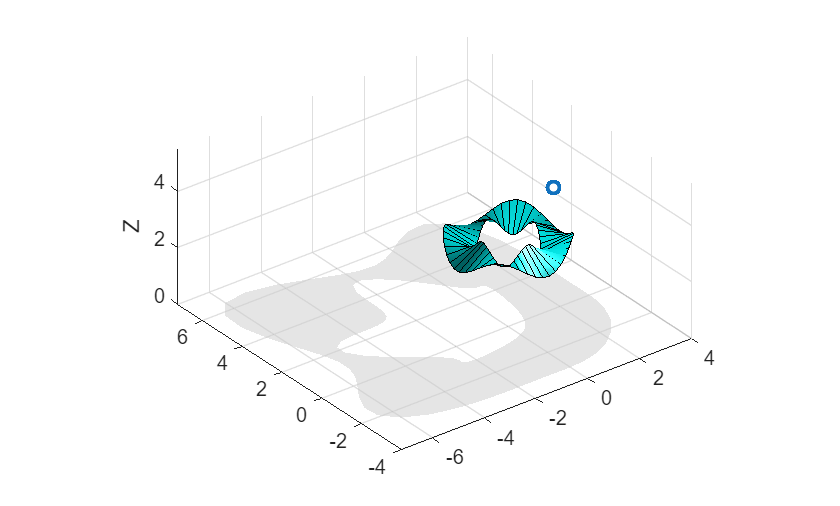

Ps = patch('Vertices',shadowVerts,'Faces',faces,...
           'FaceColor', [.8 .8 .8], 'FaceAlpha', .5, 'FaceLighting','none',...
           'EdgeColor', 'none');

Now that we have our shadow math worked out, let's create an animation.  The way shadows warp as the light source moves is always fun.  First, let's tidy up the patch edges and expand the limits so we have room to watch the shadow.

set(P,'EdgeColor','none');
axis([-10 10 -10 10 0 10])

Next, define a path for our light to follow.  We'll just do a straight line diagonally above the shape, slowly going up, so the shadow will get smaller.

path = [ linspace(-2.5,2.5,20)
         linspace(2.5,-2.5,20)
         linspace(4,6,20) ]';

Lastly, let's loop across the path, first forwards and then backwards.  We'll recompute our shadow along the way.

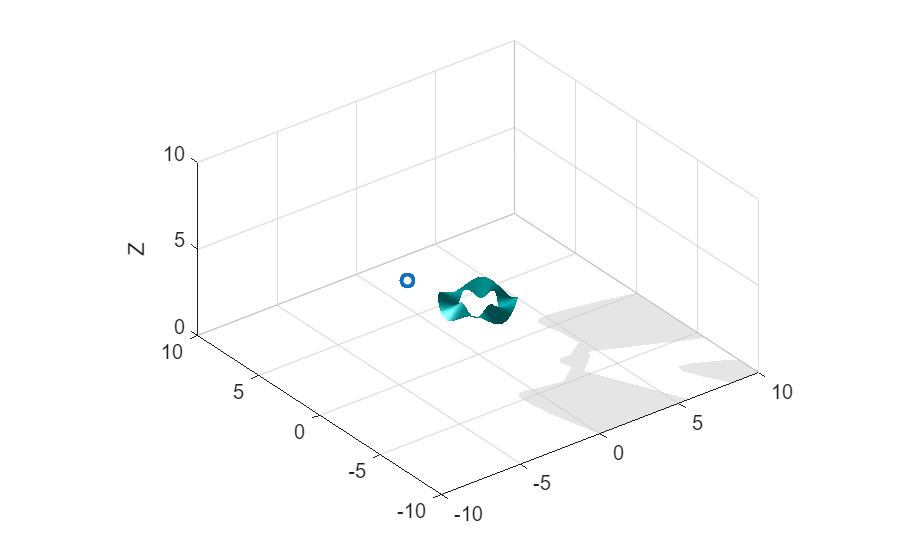

shadowVerts = zeros(size(verts));

for pidx=[1:size(path,1) size(path,1):-1:1]

    Lpos = path(pidx,:);
    offset = [Lpos(1:2) 0];

    shadowVerts(:,1:2) = Lpos(3).*(verts(:,1:2)-Lpos(1:2))./(Lpos(3)-verts(:,3))+Lpos(1:2);

    % Apply shadow to shadow patch
    set(Ps,'Vertices', shadowVerts);

    % Apply position to light
    set(L,'Position',Lpos);
    set(Lm,'XData',Lpos(1),'YData',Lpos(2),'ZData',Lpos(3));

    % Draw
    drawnow
end

WP_DELETE_IMG

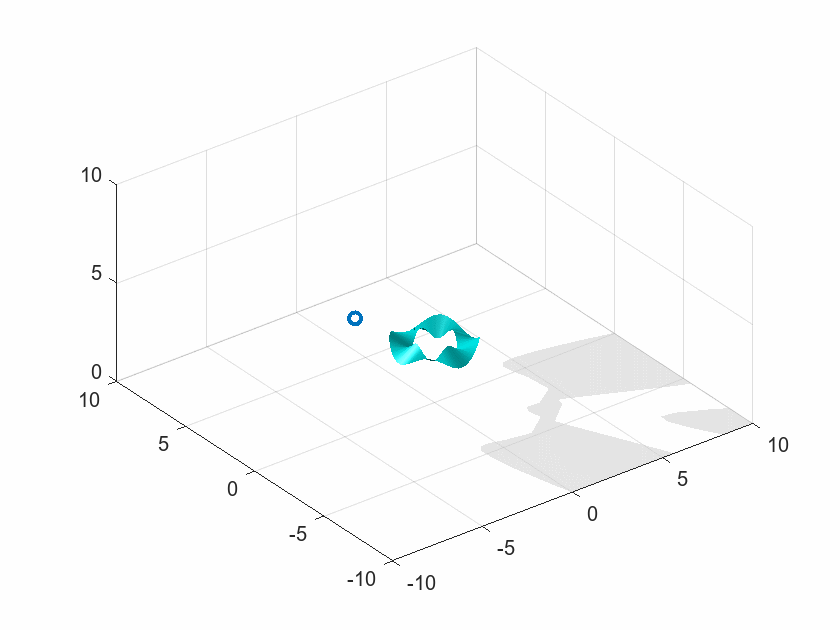

Stay tuned next week for some fun shapes and the shadows they cast.